throttle22 = repmat(throttle_interp,1,22)

throttle22 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



Ts = 0.01;  % Sample time
num_samples = length(throttle22);  % Should be 215424 if throttle was 9792 × 22

time = (0:num_samples-1) * Ts;  % Creates a 1×num_samples vector starting at 0

endurancedata = [ time; throttle22];

%save('endurancedata.mat','endurancedata')


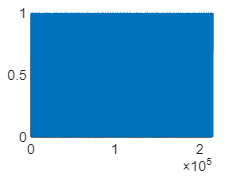


plot(endurancedata(2,:))

%formatting speed
load("endurance_speed.mat")
num_samples = 215424;
Ts = 0.01;              % Sampling interval [s]
time = (0:num_samples-1) * Ts; 


original = speed;          % size: [25258 x 1]
N_target = 215424;

x_original = linspace(0, 1, length(original));
x_target = linspace(0, 1, N_target);

speed2resampled = interp1(x_original, original, x_target, 'linear');  % or 'spline', 'pchip'
distance = sum(speed2resampled) * Ts % Total distance [m]

distance = 2.8714e+04


scale = 22000/distance;

speed2 = speed2resampled * scale;


simspeed = [time;speed2]

simspeed = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005
    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0079    0.0


%save("simspeed.mat", 'simspeed')


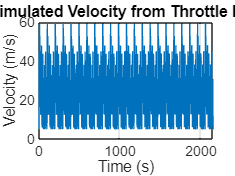

% making speed from accelerator data.

% Input data
throttle = throttle22;  % example vector, replace with your data
Ts = 0.01;  % time step
N = length(throttle);  % number of samples

% Preallocate velocity array
velocity = zeros(N, 1);

% Loop through each time step
for i = 2:N
    if throttle(i) == 1
        acceleration = 10;   % m/s^2
    else
        acceleration = -23.148;  % m/s^2
    end
    velocity(i) = velocity(i-1) + acceleration * Ts;
end

%filter cause we cant have negative accelartion

velocity = max(velocity, 0);
velocity = velocity + 5; % offset so the vehicle doesnt stop


% Plot result
time = (0:N-1)' * Ts;
plot(time, velocity);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Simulated Velocity from Throttle Map');
grid on;



distance = sum(velocity) * Ts

distance = 5.1095e+04


scale = 22000/distance

scale = 0.4306


velocityfinale = (velocity')*scale;

simspeed = [time'; velocityfinale]

simspeed = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005
    0.0022    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025    0.0025    0.0025    0.0026    0.0026    0.0027    0.0027    0.0028    0.0028    0.0028    0.0029    0.0029    0.0030    0.0030    0.0031    0.0031    0.0031    0.0032    0.0032    0.0033    0.0033    0.0034    0.0034    0.0034    0.0035    0.0035    0.0036    0.0036    0.0037    0.0037    0.0037    0.0038    0.0038    0.0039    0.0039    0.0040    0.0040    0.0040    0.0041    0.0041    0.0


save("simspeed.mat", 'simspeed')